% sistema massa-molla-smorzatore

% parametri
m = 10; c = 0.5; k = 2; %m=massa, c=coef. di attrito, k=cost. elastica

A = [0 1; -k/m -c/m];
B = [0; 1/m];
C = [1 0];
D = 0;

sys = ss(A, B, C, D);
sys_tf = tf(sys); %fdt

display(sys);


sys =
 
  A = 
          x1     x2
   x1      0      1
   x2   -0.2  -0.05
 
  B = 
        u1
   x1    0
   x2  0.1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


display(sys_tf);


sys_tf =
 
         0.1
  ------------------
  s^2 + 0.05 s + 0.2
 
Continuous-time transfer function.



s = tf('s');
R = s;

L = R*sys_tf; %cascata
display(L);


L =
 
        0.1 s
  ------------------
  s^2 + 0.05 s + 0.2
 
Continuous-time transfer function.


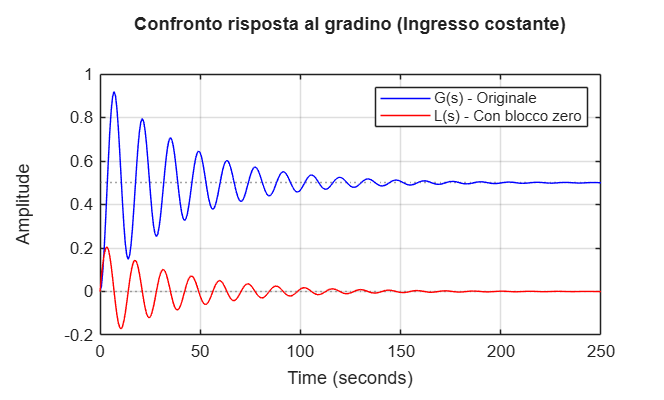


figure;
hold on;
step(sys_tf, 'b');
step(L, 'r');
legend('G(s) - Originale', 'L(s) - Con blocco zero');
title('Confronto risposta al gradino (Ingresso costante)');
grid on;